# Laboratório 5

clear
clc

P = 0.005

P = 0.0050

## Geração M-PSK

MArray = [2 4 8 16]

MArray =      2     4     8    16


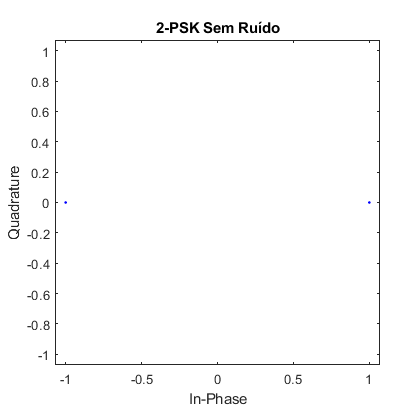

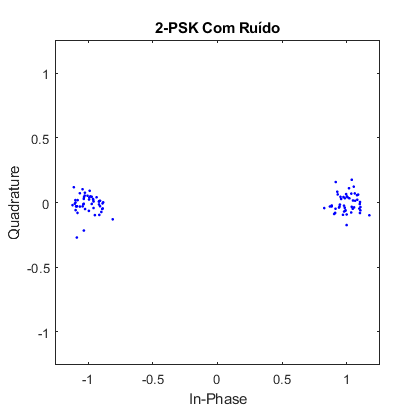

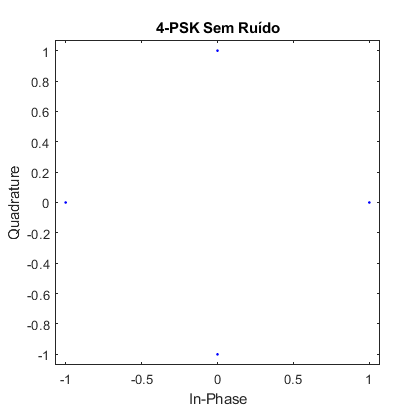

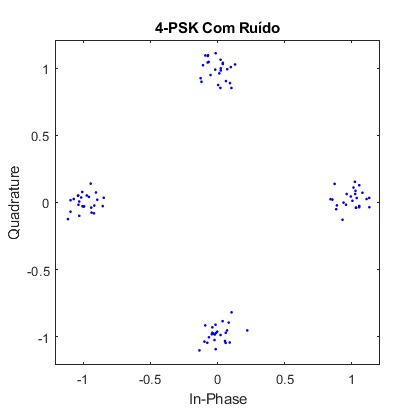

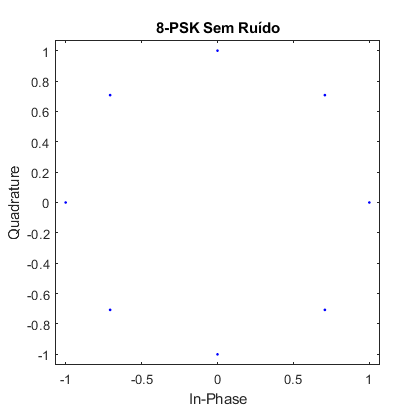

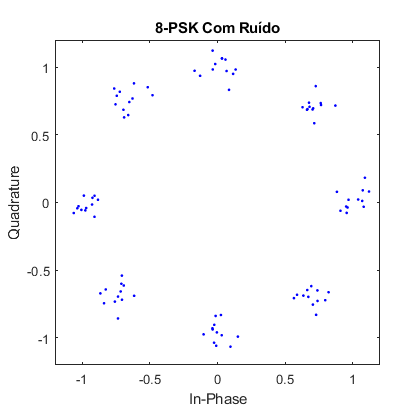

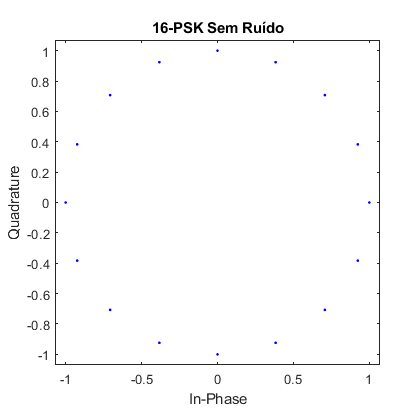

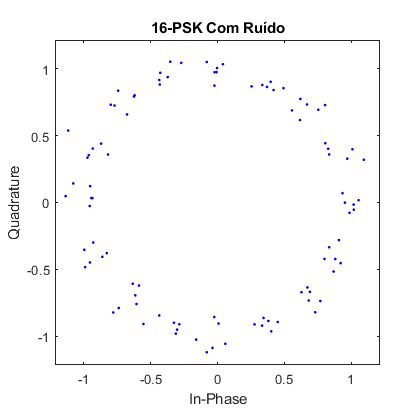

CarrierArray = zeros(1,length(MArray));

for M = 1 : length(MArray)
    
    Carrier = zeros(1, MArray(M));
    
    for i = 1 : MArray(M)
        Carrier(i) = exp(1j*(2*pi/MArray(M))*(i-1));
    end
    
    scatterplot(Carrier)
    title(sprintf("%i-PSK Sem Ruído", MArray(M)))
    
    PontosGerados = [];
    
    for i = 1 : 100/MArray(M)
        ruido = (randn(1,MArray(M)) + 1j*randn(1,MArray(M)))*sqrt(P);
        PontosGerados = [PontosGerados (Carrier + ruido)];
    end
    
    scatterplot(PontosGerados)
    title(sprintf("%i-PSK Com Ruído", MArray(M)))
end

## Geração M-QAM


MArray = [4 16 64]

MArray =      4    16    64


range =     -1     1


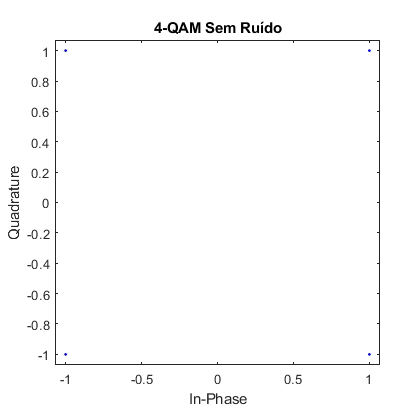

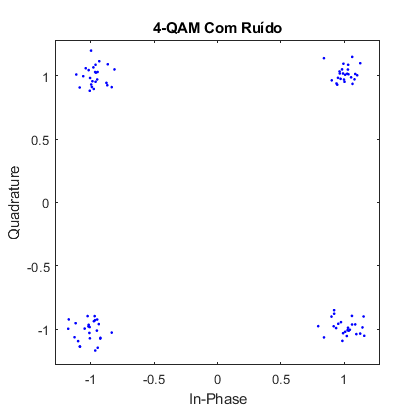

range =     -3    -1     1     3


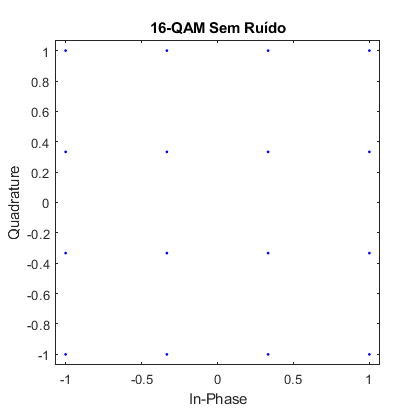

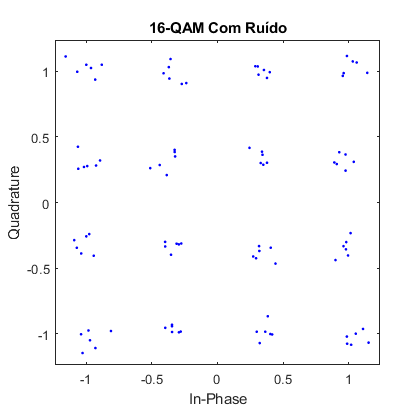

range =     -7    -5    -3    -1     1     3     5     7


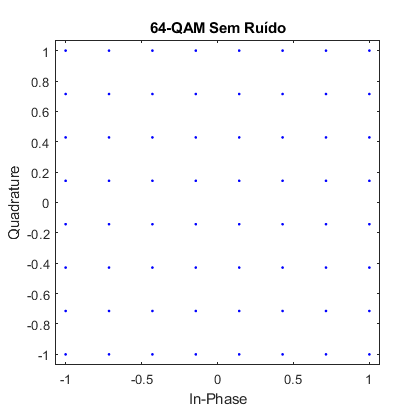

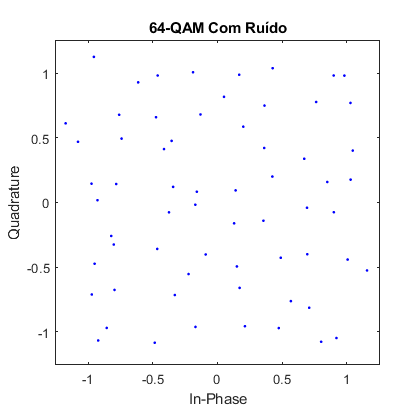


for M = 1 : length(MArray)
    Carrier = [];
    range = -sqrt(MArray(M))+1:2:sqrt(MArray(M))
    for i = range
        for k = range
            Carrier = [Carrier (i+1j*k) / (sqrt(MArray(M))-1)];
        end
    end
    scatterplot(Carrier)
    title(sprintf("%i-QAM Sem Ruído", MArray(M)))

    
    PontosGerados = [];
    
    for i = 1 : 100/MArray(M)
        ruido = (randn(1,MArray(M)) + 1j*randn(1,MArray(M)))*sqrt(P);
        PontosGerados = [PontosGerados (Carrier + ruido)];
    end
    scatterplot(PontosGerados)
    title(sprintf("%i-QAM Com Ruído", MArray(M)))
end